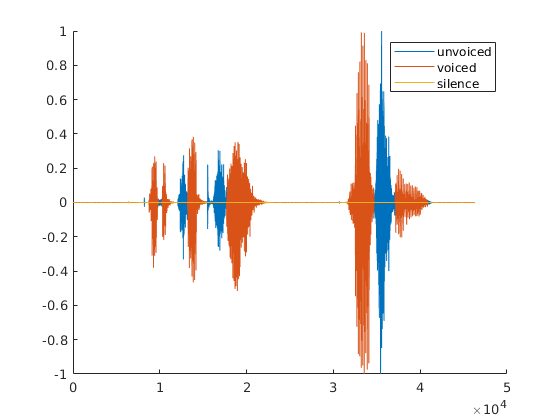

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

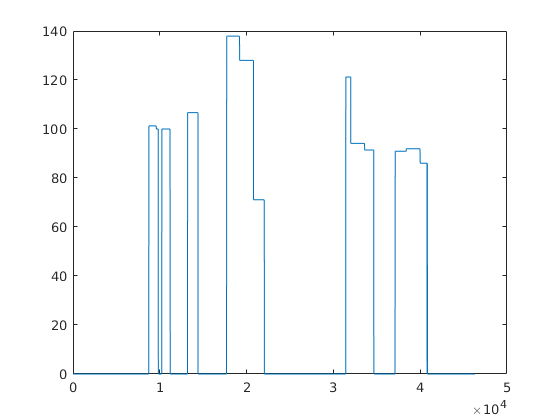


figure;
plot(f0);

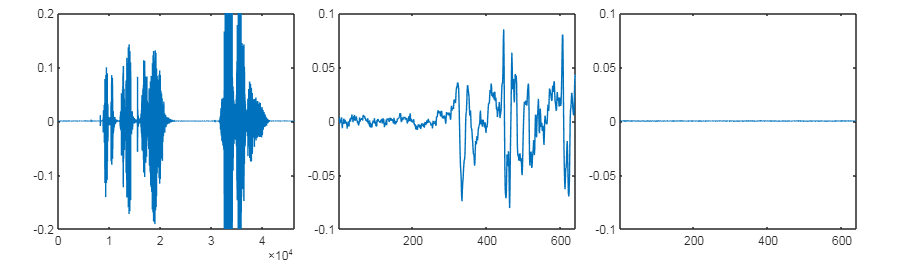

[x, fs] = audioread("percepcja.wav");
win = round(fs * 0.04);
figure("Position", [0 0 1000 300]);
tiledlayout(1,3,'TileSpacing','Compact','Padding','Compact');
% cały sygnał
nexttile
plot(x);
ylim([-0.2 0.2]);
% fragment E
e_crop = x(10000:10000+win);
nexttile;
plot(e_crop)
xlim([1 win]);
ylim([-0.1 0.1]);
% fragment S
s_crop = x(25000:25000+win);
nexttile;
plot(s_crop);
xlim([1 win]);
ylim([-0.1 0.1]);

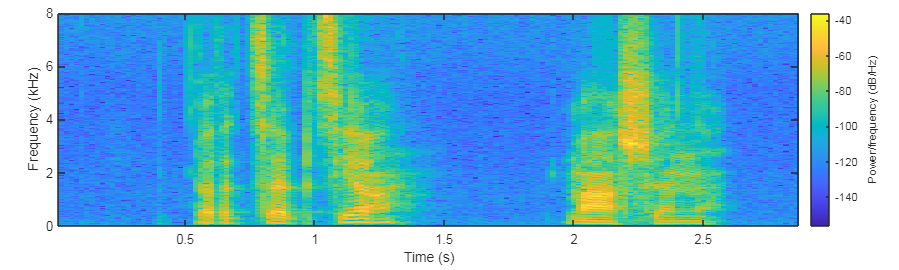

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/2, [], fs, 'yaxis');

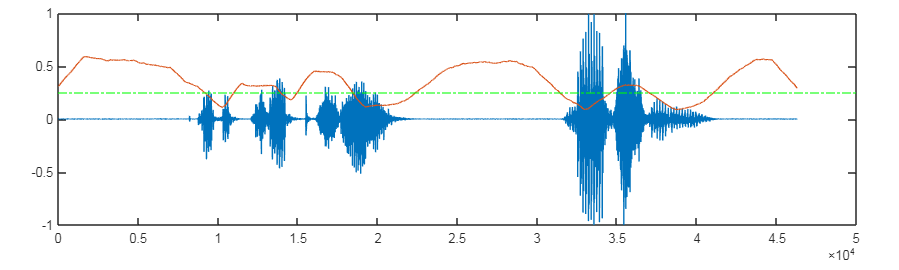

x1 = x;
x2 = [0; x(1:end-1)];
diff = sign(x1) ~= sign(x2);
zcr = conv(diff, ones(1, win) / win, "same");
figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x / max(x));
ylim([-1 1])
hold on;
plot(zcr);
hold on;
yline(0.25,'-.g')

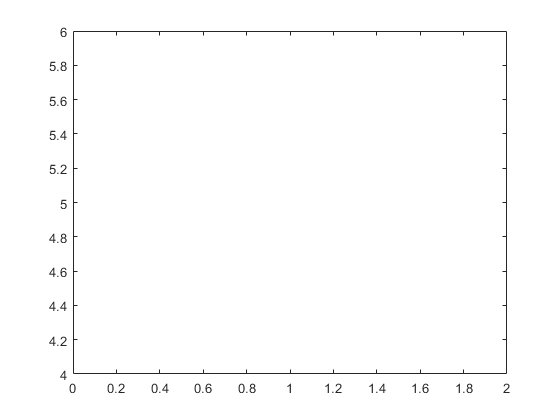

test.val = [1,2,3,4,5];
test.col = ['r','g','b','y','c'];
figure;
for i=1:5
    plot(test.val(i),test.col(i))
end

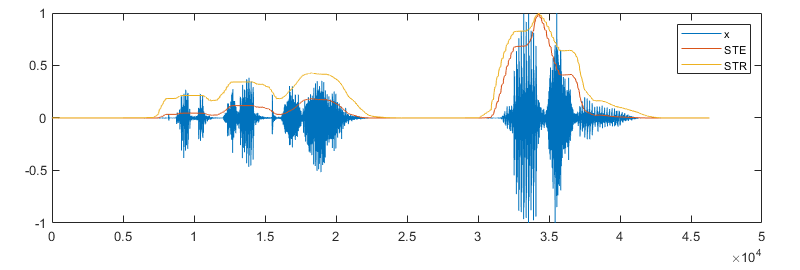

% wczytanie i normalizacja nagrania
[x, fs] = audioread("percepcja.wav");
x = x - mean(x);
x = x / max(x);
figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x);
ylim([-1 1]);
% długość okna analizy: 200 ms
win = round(fs * 0.2);
% energia chwilowa
ste = conv(x.^2, ones(1,win), 'same');
ste = ste / max(ste);
% wersja z pierwiastkiem
str = sqrt(ste);
hold on;
plot(ste);
plot(str);
legend("x", "STE", "STR");

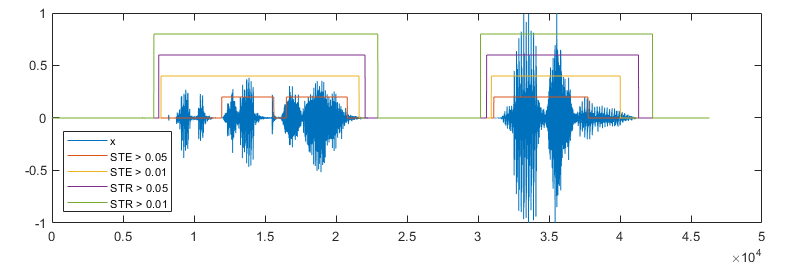

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x);
ylim([-1 1]);
hold on;
plot(0.2 * (ste > 0.05));
plot(0.4 * (ste > 0.01));
plot(0.6 * (str > 0.05));
plot(0.8 * (str > 0.01));
legend("x", "STE > 0.05", "STE > 0.01", "STR > 0.05", "STR > 0.01", "Location", "southwest");